# ETSMP Q2 eksamen – 2015-16

## Opgave 1: Stokastiske Variable

format rat

Lad den simultane tæthedsfunktion for to discrete stokastiske variable X og Y være angivet som tabellen:  

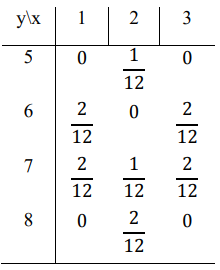

1) Vis at de marginale tæthedsfunktioner for X og Y er givet ved:

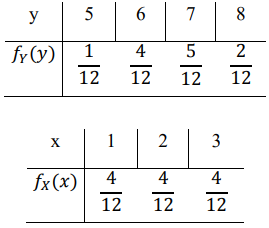

X = [1 2 3];
Y = [5 6 7 8];
XY_SIM = [0 1/12 0; 2/12 0 2/12; 2/12 1/12 2/12; 0 2/12 0];

Marginal sandsynlighed for x:

X_MAR = sum(XY_SIM);
disp(X_MAR)

       1/3            1/3            1/3     



Marginal sandsynlighed for y:

Y_MAR = sum(XY_SIM,2);
disp(Y_MAR')

       1/12           1/3            5/12           1/6     



2) Vis at:

EX = sum(X.*X_MAR)

EX =        2       


## 

EY = sum(Y*Y_MAR)

EY =       20/3     


##  

EXY = EX*EY

EXY =       40/3     


## 

EX2 = sum(X.^2.*X_MAR)

EX2 =       14/3     


EY2 = sum(Y.^2*Y_MAR)

EY2 =      271/6     


3) Hvad er korrelationskoefficenten for X og Y? 

                   

sigmaX = sqrt(EX2-(EX.^2));
sigmaY = sqrt(EY2-(EY.^2));

rho = (EXY - EX .* EY) / (sigmaX * sigmaY)

rho =        0       


4) Angiv om de stokastiske variable X og Y er korrelerede. 

Da korrelationskoefficienten fra 3) er lig 0, er X og Y ukorrelerede.

5) Angiv om de stokastiske variable X og Y er uafhængige. 

disp(X_MAR.*Y_MAR)

       1/36           1/36           1/36    
       1/9            1/9            1/9     
       5/36           5/36           5/36    
       1/18           1/18           1/18    



Da $f_X \left(x\right)*f_Y \left(y\right)$ ikke er identisk med $f_{\mathrm{XY}} \left(x,y\right)$ er X og Y ikke uafhægige.

6) Opskriv den betingede sandsynlighed $f_{X|Y} \left(x|y=6\right)$

Da $y=6$ tages række to fra tabellen over tæthedsfunktionen

fxy = XY_SIM(2,:)./Y_MAR(2);
disp(fxy)

       1/2            0              1/2     



## Opgave 2: Stokastiske Processer

format rat

En diskret stokastisk process er givet ved: 

$X\left(n\right)=w\left(n\right)$,

$w\left(n\right)$ angives desuden til at være i.i.d. efter en uniform fordeling med $w\left(n\right)~U\left(0,10\right)$. 

1) Skitsér 10 samples af én realisation af processen $X\left(n\right)$. Dvs. for $n=1,\ldotp \ldotp \ldotp ,10$. 

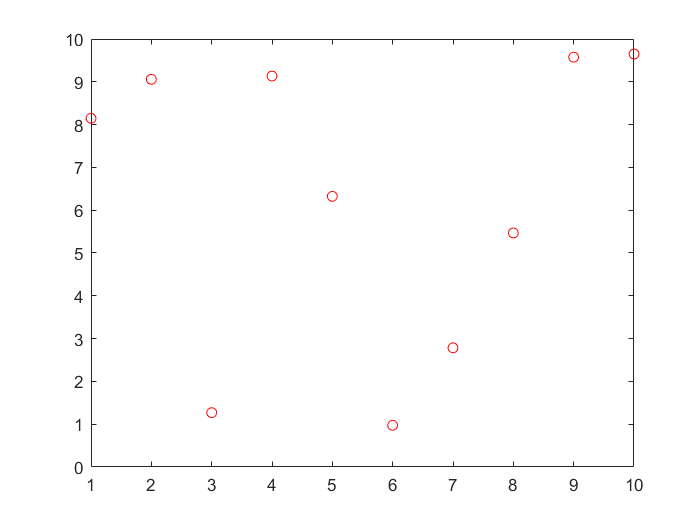

a = 0; b = 10;
Xn = a + (b-a).*rand(1,10);
plot(Xn,'ro')

2) Bestem ensemble middelværdien og variansen for processen $X\left(n\right)$.

## 

ensemble_mean = (a+b)/2

ensemble_mean =        5       


ensemble_variance = ((b-a)^2)/12

ensemble_variance =       25/3     


3) Bestem autokorrelationsfunktionen $R_{\mathrm{XX}} \left(\tau \right)$ for processen $X\left(n\right)$ for $\tau =0,\ldotp \ldotp \ldotp ,3$.

4) Angiv om processen er WSS (stationær i den brede forstand) og om den er ergodisk, begrund dine svar.  

Da middelværdi $E\left\lbrack X\left(n\right)\right\rbrack$ er uafhængig af n, og $E\left\lbrack {X\left(n\right)}^2 \right\rbrack$ er uafhængig af n, kan $X\left(n\right)$ siges at være stationær i den brede forstand, WSS.

Processen $X\left(n\right)$ er ergodisk, da den tidslige, over n, fordelingsfunktion er identisk med fordelingsfunktionen for ensemble.

## Opgave 3: Sandsynlighedsregning

format rat

Laktoseintolerans er tilstede hos 20% af den finske befolkning. Hvis en finne har laktoseintolerans, vil en test give en positiv test i 90% af tilfældene. Hvis finnen ikke har sygdommen, vil testen give en positiv test i 30% af tilfældene. 

Event A: Finne har laktoseintolerance 

Event B: Test er positiv

`Prior: Sandsynlighed for at en finne har laktoseintolerans`

`Prior: Sandsynlighed for at en finne ikke har laktoseintolerans`

       

`Likelihood: Sandsynlighed for en positiv test givet at en en finne har laktoseintolerans`

`Likelihood: Sandsynlighed for en positiv test givet at en en finne ikke har laktoseintolerans`

1) Beregn den totale sandsynlighed for at få en positiv test for en finne, hvor det er ukendt om han har laktoseintolerans. 

`Total Probality: Sandsynligheden for at en finne har en positiv test (Sum Rule)`

PrA = 0.2; PrNA = 1-PrA; PrBA = 0.9; PrBNA = 0.3; 

PrB = PrBA * PrA + PrBNA * PrNA

2) Hvis en finne har en positiv test, hvad er sandsynligheden for, at han også har sygdommen? 

`Posterior: Sandsynligheden for at en finne har laktoseintolereans givet en positiv test (Bayes Rule)`

PrAB = (PrBA * PrA) / PrB

## Opgave 4: Statistik

format shorteng

Antal: er dødelighed af drenge under 1 år i Danmark fra 1901 til 1991. Det er angivet i tabellen1 :  

1) Plot data fra tabellen, og optegn den bedste rette linie gennem punkterne ved at bestemme skæringen med y-aksen og hældningen af den lineære model. Angiv hvilken metode, der er anvendt til at finde den lineære model. 

Skæring med y-aksen kan findes ved 

Hældningen af den lineære model kan findes ved

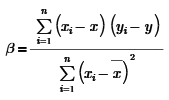

counts = [5562 4357 3471 3078 2309 1285 969 692 238 268];
years = [1901 1911 1921 1931 1941 1951 1961 1971 1981 1991];
count_mean = mean(counts)

count_mean =      2.2229e+003


year_mean = mean(years)

year_mean =      1.9460e+003


% Hældning
beta = sum((counts - count_mean) .* (years - year_mean)) / sum((years - year_mean).^2)

beta =    -59.2273e+000


% Skæring
alpha = count_mean - beta * year_mean

alpha =    117.4792e+003


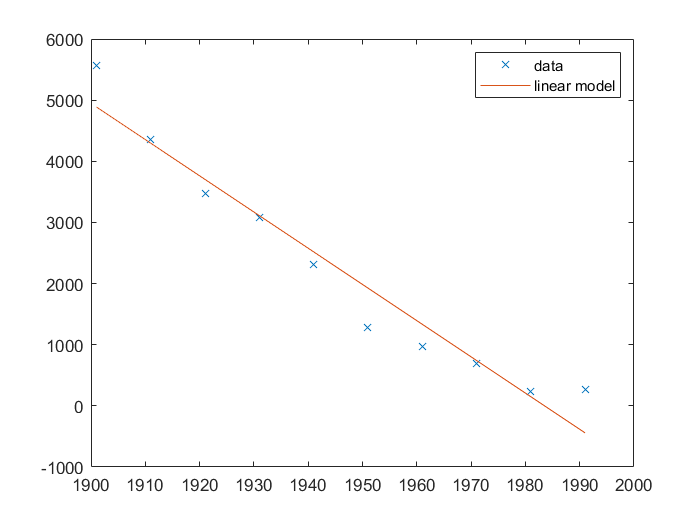

linear_model = alpha + years * beta;

figure(1)
plot(years,counts,'x');
hold on
plot(years,linear_model);
legend('data','linear model');

2) Lav en residualtegning.  

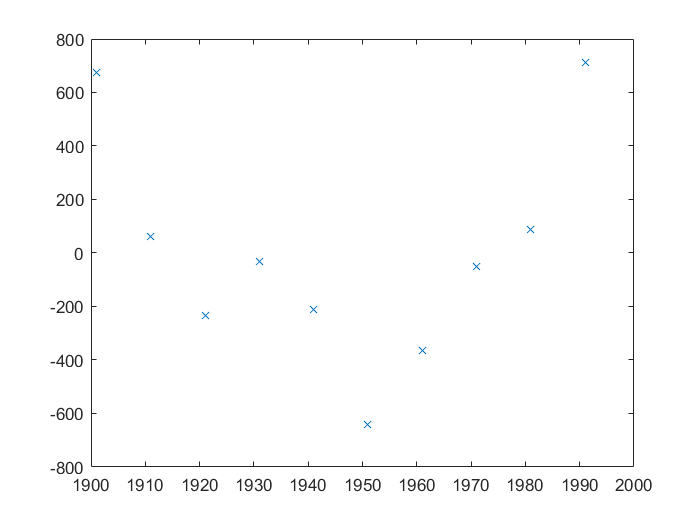

residual = counts - linear_model;

figure(2)
plot(years,residual,'x');

3) Beregn et 95% konfidensinterval for hældningen.

Først findes den inverse student t fordeling for 8 frihedsgrader og 95% konfidensinterval.

% Antal frihedsgrader n-2
n = length(counts)

n =     10.0000e+000


% Inivers student t fordeling
t0 = tinv(0.975,(n-2))

t0 =      2.3060e+000


sr = 1/(n-2)*(sum(residual.^2))

sr =    202.1808e+003


lower_bound = beta - t0 *sqrt(sr/sum((years - year_mean).^2))

lower_bound =    -70.6430e+000


upper_bound = beta + t0 *sqrt(sr/sum((years - year_mean).^2))

upper_bound =    -47.8116e+000


4) Ud fra svaret i opgave 2 og 3, vil du konkludere at antagelsen om linearitet mellem dødelighed og årstal er rimelig? 

Der er umiddelbart for få målepunkter. Dog er der en lineær tendens, men residualplottet viser at residualerne systematisk ligger under 0 mellem 1920 og 1970, desuden vil data forventes at afvige mere efter år 1991, da dødeligheden ikke kan være negativ.

Linearitet er ikke en god antagelse.